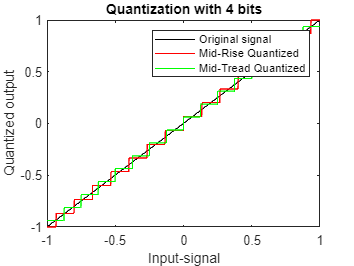

input_signal = linspace(-1, 1, 1000);
num_bit = 4; % number of bits for quantization

% MID-RISE Quantization
quantized_midrise = midRiseQuantization(input_signal, num_bit);

% MID-TREAD Quantization
quantized_midtread = midTreadQuantization(input_signal, num_bit);

% Plot the result
figure;
plot(input_signal, input_signal, '-k', input_signal, quantized_midrise, 'r', input_signal, quantized_midtread, 'g');
legend('Original signal', 'Mid-Rise Quantized', 'Mid-Tread Quantized');
xlabel('Input-signal');
ylabel('Quantized output'); % Fixed the typo in ylabel
title(['Quantization with ', num2str(num_bit), ' bits']); % Fixed the typo in title

function quantized_signal = midRiseQuantization(input_signal, num_bits)
    % Define the quantization levels
    quant_levels = linspace(-1, 1, 2^num_bits);

    % Quantize the input signal
    quantized_signal = zeros(size(input_signal));

    for i = 1:length(input_signal)
        [~, index] = min(abs(input_signal(i) - quant_levels));
        quantized_signal(i) = quant_levels(index);
    end
end

function quantized_signal = midTreadQuantization(input_signal, num_bits)
    % Define the quantization levels
    quant_levels = linspace(-1 + 1/(2^num_bits), 1 - 1/(2^num_bits), 2^num_bits);

    % Quantize the input signal
    quantized_signal = zeros(size(input_signal));

    for i = 1:length(input_signal)
        [~, index] = min(abs(input_signal(i) - quant_levels));
        quantized_signal(i) = quant_levels(index);
    end
end

